addpath('functions/')

Read full protocol

fp = readtable("data/KBM_export_sql_sam/full_protocol.csv", TextType="string");
fp.PENTAD = latlon2pentad(fp.centrey, fp.centrex);

Exctract eBird data from add_hoc based on user ID

eb = readtable("data/KBM_export_sql_sam/add_hoc.csv", TextType="string");
eb.PENTAD = latlon2pentad(eb.centrey, eb.centrex);
eb = eb(eb.observer_no==22829,:);

Merge species

sp_kbm = readtable("../KenyaAtlasComparison/data/kbm/sp_kbm.xlsx", TextType="string");
[~, id] = ismember(eb.spp, sp_kbm.Ref);
eb.SEQ(:) = 0;
eb.SEQ(id~=0) = sp_kbm.SEQ(id(id~=0));
[~, id] = ismember(fp.spp, sp_kbm.Ref);
fp.SEQ(:) = 0;
fp.SEQ(id~=0) = sp_kbm.SEQ(id(id~=0));

Species_list

eb.common_name = eb.common_name + " " + eb.common_group;
fp.common_name = fp.common_name + " " + fp.common_group;
sp = [eb; fp];
sp = unique(sp(:,["SEQ","common_name"]));

Remove unknown (rare? species)

sortrows(groupsummary(fp(fp.SEQ==0,:),"common_name"), "GroupCount", "descend")

ans = 236×2 table
              common_name              GroupCount
    _______________________________    __________

    "Unknown Unknown"                     665    
    "Long-tailed Glossy Starling"         148    
    "Burchell's Coucal"                    76    
    "African Collared Dove"                75    
    "Sharpe's Drongo"                      75    
    "Southern White-crowned Shrike"        72    
    "Yellow-throated Bush Sparrow"         56    
    "Southern Grey-headed Sparrow"         51    
    "Kivu Ground-thrush"                   48    
    "Griffon Vulture"                      40    
    "Somali Bulbul"                        31    
    "Brown-headed Apalis"                  30    
    "Great Sparrow"                        27    
    "Red-chested Goshawk"                  25    
    "Grey Go-away-bird"                    21    
    "White-crowned Lapwing"                21    


sortrows(groupsummary(eb(eb.SEQ==0,:),"common_name"), "GroupCount", "descend")

ans = 10×2 table
                                        common_name                                         GroupCount
    ____________________________________________________________________________________    __________

    "Western Black-headed Batis"                                                                23    
    "Unidentified Wader"                                                                        17    
    "Unidentified Tern"                                                                         15    
    "Marsh Tchagra"                                                                             10    
    "Unidentified Duck"                                                                         10    
    "Gosling's Bunting"                                                                          5    
    "African Owls (unidentified) Owl"                                                     

fp=fp(fp.SEQ~=0,:);
eb=eb(eb.SEQ~=0,:);

Problematic taxon

SEQ_pb = [678]

Number of sightings (KBM): 574161


Number of sightings (eBird): 181128


## Basic overview

disp("Number of sightings (KBM): " + height(fp))

Number of card (KBM): 11910


disp("Number of sightings (eBird): " + height(eb))

Number of card (eBird): 4736


disp("Number of card (KBM): " + numel(unique(fp.card_no)))

Number of species (KBM): 1054


disp("Number of card (eBird): " + numel(unique(eb.card_no)))

Number of species (eBird): 1097


disp("Number of species (KBM): " + numel(unique(fp.SEQ)))
disp("Number of species (eBird): " + numel(unique(eb.SEQ)))

Create map/grid for plotting

abm = jsondecode(fileread(("data/kbm/coverage_KE.geojson")));
extend=nan(2,2);
for i_f = 1:numel(abm.features)
    extend(1,1) = min(extend(1,1), min(abm.features(i_f).geometry.coordinates(:,:,:,1)), "omitnan");
    extend(1,2) = min(extend(1,2), min(abm.features(i_f).geometry.coordinates(:,:,:,2)), "omitnan");
    extend(2,1) = max(extend(2,1), max(abm.features(i_f).geometry.coordinates(:,:,:,1)), "omitnan");
    extend(2,2) = max(extend(2,2), max(abm.features(i_f).geometry.coordinates(:,:,:,2)), "omitnan");
end
extend(1,1) = floor(min(extend(1,1),min(fp.centrey)));
extend(1,2) = floor(min(extend(1,2),min(fp.centrex)));
extend(2,1) = ceil(max(extend(2,1),max(fp.centrey)));
extend(2,2) = ceil(max(extend(2,2),max(fp.centrex)));
g.res = 5 / 60;
g.lon = (extend(1,1)-g.res/2):g.res:(extend(2,1)+g.res/2);
g.lat = (extend(1,2)-g.res/2):g.res:(extend(2,2)+g.res/2);
[g.LAT,g.LON] = meshgrid(g.lat,g.lon);

compute pentad code

g.pentad = latlon2pentad(g.LAT, g.LON);

cell-centered

g.lon = g.lon + g.res/2;
g.lat = g.lat + g.res/2;
[g.LAT,g.LON] = meshgrid(g.lat,g.lon);

Compute coverage (total number of card per pentad and total number of sightings

gfp = zeros(numel(g.lat), numel(g.lon),2);
tmp = groupsummary(fp,["card_no" "pentad"]);
tmp2 = groupsummary(tmp,"pentad",@sum,"GroupCount");
for i=1:height(tmp2)
    id = strcmpi(tmp2.pentad(i), g.pentad);
    assert(sum(id(:))>0)
    [i1,i2]=ind2sub(size(id),find(id));
    gfp(i2,i1,1) = tmp2.GroupCount(i);
    gfp(i2,i1,2) = tmp2.fun1_GroupCount(i);
end

Same for ebird

geb = zeros(numel(g.lat), numel(g.lon),2);
tmp = groupsummary(eb,["card_no" "pentad"]);
tmp2 = groupsummary(tmp,"pentad",@sum,"GroupCount");
for i=1:height(tmp2)
    id = strcmpi(tmp2.pentad(i), g.pentad);
    assert(sum(id(:))>0)
    [i1,i2]=ind2sub(size(id),find(id));
    geb(i2,i1,1) = tmp2.GroupCount(i);
    geb(i2,i1,2) = tmp2.fun1_GroupCount(i);
end

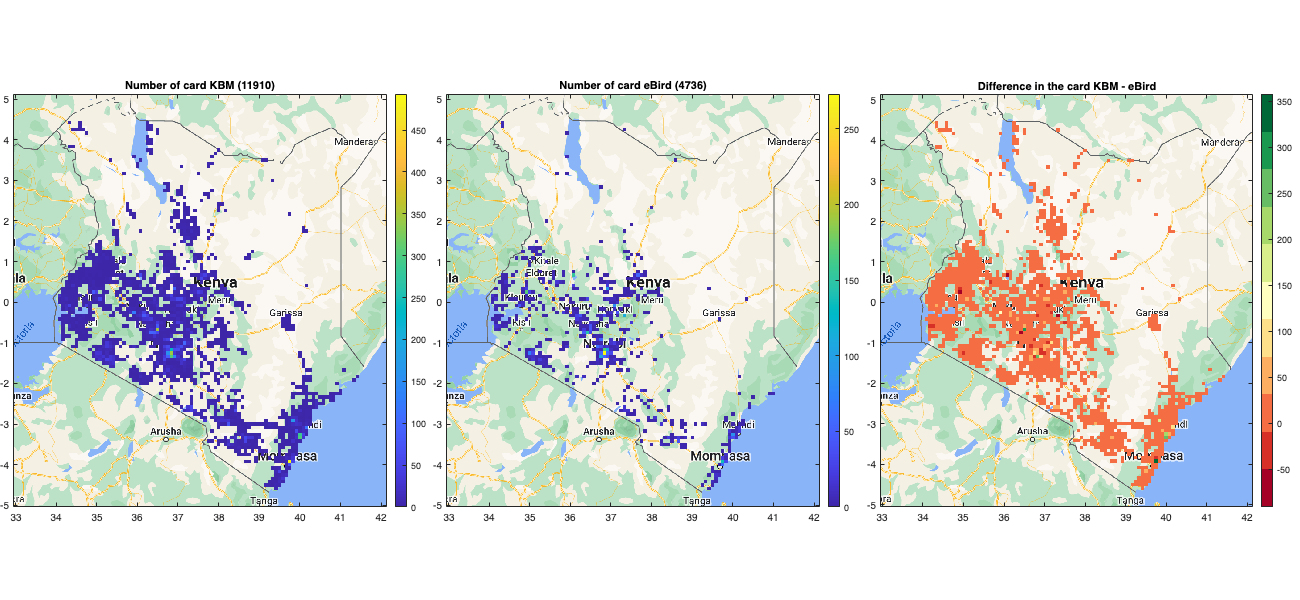

i = 1; % card, 2: sightings
figure('position',[0 0 1300 600]); tiledlayout(1,3,'TileSpacing','tight','Padding','tight')
nexttile;hold on; box on
n_gfp = sum(gfp(:,:,i),'all');
imagesc(g.lon,g.lat, gfp(:,:,i),'alphadata',gfp(:,:,i)~=0)
axis equal tight; set(gca,"YDir","normal"); plot_google_map; %clim([0 .05])
title("Number of card KBM ("+n_gfp+")"); colorbar;
nexttile; hold on; box on
n_geb = sum(geb(:,:,i),'all');
imagesc(g.lon,g.lat,geb(:,:,i),'alphadata',geb(:,:,i)~=0)
axis equal tight; set(gca,"YDir","normal"); plot_google_map; %clim([0 .05])
title("Number of card eBird ("+n_geb+")"); colorbar;
a=nexttile; hold on; box on
tmp = gfp(:,:,i) - geb(:,:,i);
imagesc(g.lon,g.lat,tmp,'alphadata',(gfp(:,:,i) + geb(:,:,i))~=0)
axis equal tight; set(gca,"YDir","normal"); plot_google_map; %clim([-1 1]*.025)
colormap(a, brewermap(11,"RdYlGn")); colorbar;
title("Difference in the card KBM - eBird")

Coverage map shows that KBM has a larger coverage, consistent with its higher number of card. The difference in the number of cards per pentad (3rd subfigure) does not show clear trend. The green Mombasa pentad is due to Doris

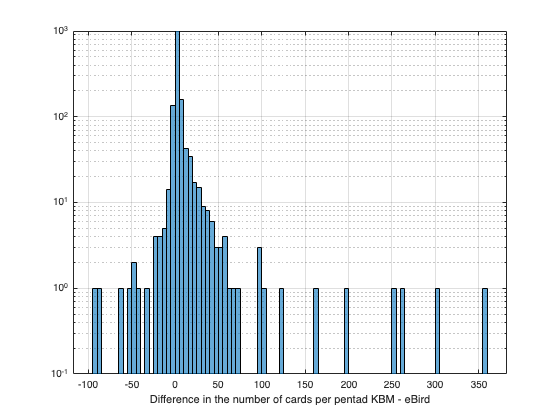

figure; box on; hold on; grid on;
tmp1 = gfp(:,:,i); 
tmp2 = geb(:,:,i); 
id = (tmp1 + tmp2)>0;
tmp1 = tmp1(id);
tmp2 = tmp2(id);
tmp = tmp1 - tmp2;
histogram(tmp);
yline(0)
ylim([0.1 1000])
set(gca,'YScale','log')
xlabel("Difference in the number of cards per pentad KBM - eBird")

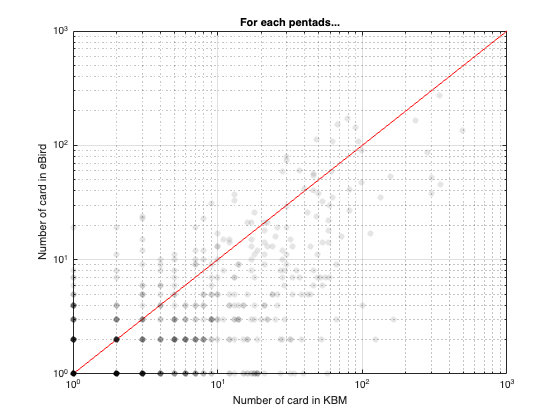

figure; box on; hold on; grid on;
plot([1 1e3], [1 1e3],'-r')
scatter(tmp1,tmp2,'filled','k',MarkerFaceAlpha=.1)
set(gca,'YScale','log')
set(gca,'XScale','log')
xlabel("Number of card in KBM")
ylabel("Number of card in eBird")
title("For each pentads...")

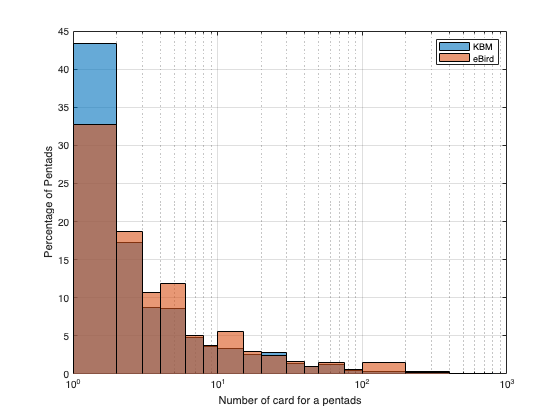

figure; box on; hold on; grid on;
bins = [0:3 4:2:10 15 20:10:50 75 100 200 400 800];%10.^(0:.1:3);
tmp = gfp(:,:,i); tmp = tmp(tmp>0);
histogram(tmp, bins, Normalization="percentage")
tmp = geb(:,:,i); tmp = tmp(tmp>0);
histogram(tmp, bins, Normalization="percentage")
set(gca,'XScale','log')
legend(["KBM","eBird"]);
ylabel("Percentage of Pentads")
xlabel("Number of card for a pentads")

When normalizing for the number of card, KBM has relatively more pentads with a unique card. But the ratio for pentads with +2 cards is relatively the same. This demonstrate that KBM user tend to visit un-visited pentads, but only for a single card, then there is not much difference. 

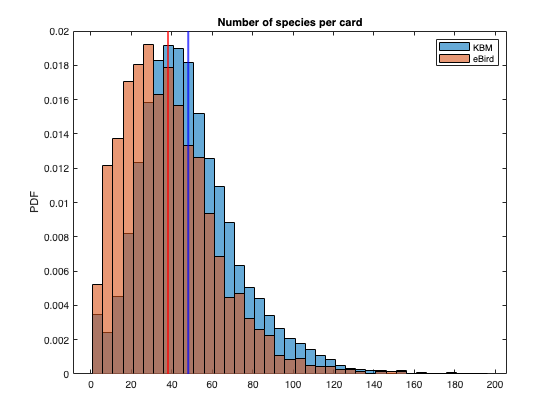

tmp1 = groupsummary(fp,"card_no", @numel, "spp");
tmp2 = groupsummary(eb,"card_no", @numel, "spp");
figure; box on; hold on;
histogram(tmp1.fun1_spp, 1:5:200,Normalization="pdf")
histogram(tmp2.fun1_spp, 1:5:200, Normalization="pdf")
xline(mean(tmp1.fun1_spp),"b",LineWidth=2)
xline(mean(tmp2.fun1_spp),"r",LineWidth=2)
legend(["KBM","eBird"]);
ylabel("PDF")
title("Number of species per card")

- KBM cards have on average a higher number of species (48 against 38).

- The entire distribution on eBird is shifted to the left. Arguably, eBird user do not search to maximize the number of species and might not cover the pentad with the same effor than in KBM (e.g. searching for rarest bird). 

- In addition, eBird might be prone to report complete checklist even if it is not. 

- In addition, eBird user might be less good than KBM user and miss more species?

- Or, eBird user let their checklist run resulting in the 2h mark while they are not actively birding (e.g. eating on a terasse etc...)

In both dataset, we have a lot of cards with very few birds. Probably some errors in the effort reported.

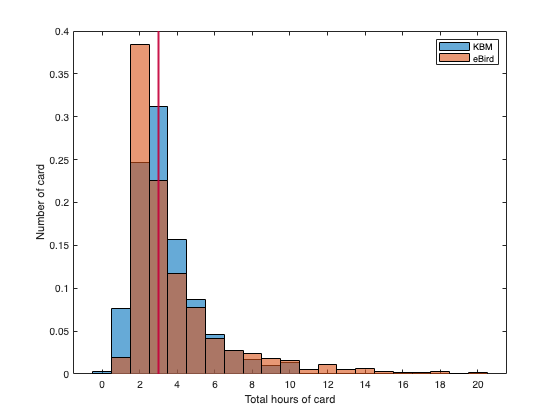

tmp1 = groupsummary(fp,"card_no", @median, "total_hours");
tmp2 = groupsummary(eb,"card_no", @median, "total_hours");
figure; box on; hold on;
histogram(tmp1.fun1_total_hours, -.5:20.5, Normalization="pdf")
histogram(tmp2.fun1_total_hours, -.5:20.5, Normalization="pdf")
xline(median(tmp1.fun1_total_hours),"b",LineWidth=2)
xline(median(tmp2.fun1_total_hours),"r",LineWidth=2)
legend(["KBM","eBird"]);
ylabel("Number of card");
xlabel("Total hours of card");

Note that the data is rounded to the hour. 

Why does eBird data peak slight earlier than KBM?

### Reporting rate

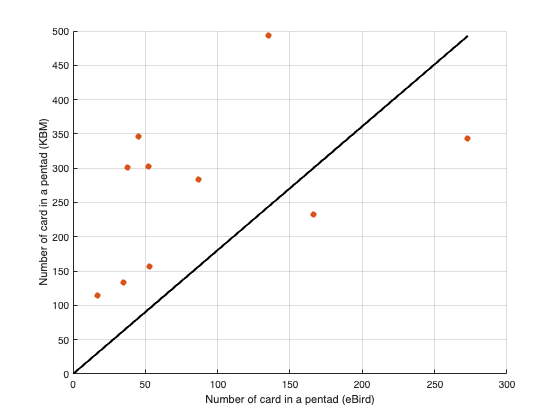

% only pentad with same number of card eBird vs KBM
id = (abs(gfp(:,:,1)- geb(:,:,1))./(gfp(:,:,1) + geb(:,:,1)))<= 0.9 & gfp(:,:,1)>100;
auz_pentad = g.pentad(id');
tmp=geb(:,:,1); tmp2=gfp(:,:,1);
figure; hold on; grid on;
plot([0 max(tmp(id))], [0 max(tmp2(id))],'k', LineWidth=2)
scatter(tmp(id),tmp2(id),'filled');
xlabel("Number of card in a pentad (eBird)");
ylabel("Number of card in a pentad (KBM)");

fpf = fp; fpf = fpf(ismember(fpf.pentad,auz_pentad),:);
ebf = eb; ebf = ebf(ismember(ebf.pentad,auz_pentad),:);

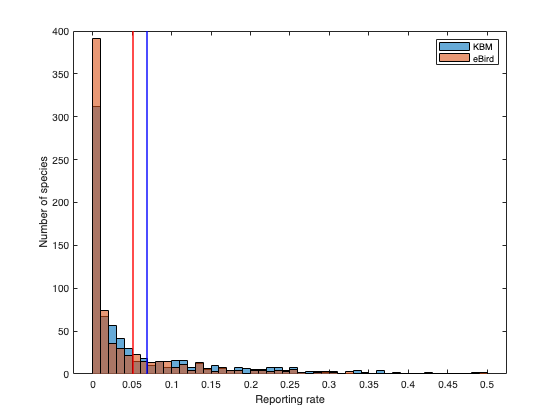

tmp1 = groupcounts(fpf,"SEQ");
tmp1.Properties.VariableNames(2)="KBM";
tmp2 = groupcounts(ebf,"SEQ");
tmp2.Properties.VariableNames(2)="eBird";
tmp = outerjoin(tmp1(:,1:2), tmp2(:,1:2), Keys="SEQ");
tmp.SEQ = tmp.SEQ_left;
tmp.SEQ(isnan(tmp.SEQ)) = tmp.SEQ_right(isnan(tmp.SEQ));
tmp = removevars(tmp,['SEQ_right', "SEQ_left"]);
tmp.KBM(isnan(tmp.KBM))=0;
tmp.KBM_frac = tmp.KBM ./ numel(unique(fpf.card_no));
tmp.eBird(isnan(tmp.eBird))=0;
tmp.eBird_frac = tmp.eBird ./ numel(unique(ebf.card_no));
% tmp.common_name = sp.common_name(ismember(tmp.spp, sp.spp));


figure; box on; hold on;
histogram(tmp.KBM_frac, 0:.01:.5)
histogram(tmp.eBird_frac, 0:.01:.5)
xline(mean(tmp.KBM_frac),"b",LineWidth=2)
xline(mean(tmp.eBird_frac),"r",LineWidth=2)
legend(["KBM","eBird"]);
ylabel("Number of species");
xlabel("Reporting rate");

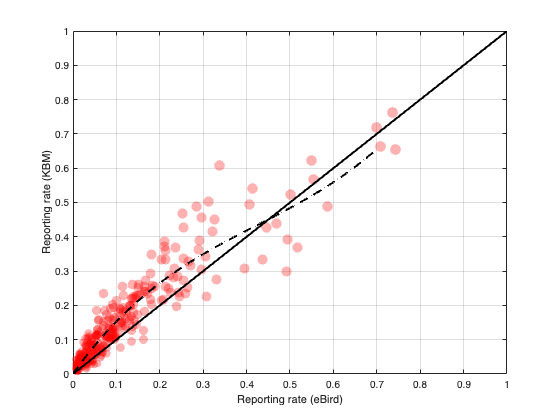

% Only select species with at least xx  records for both KBM and eBird
id = tmp.eBird>5 & tmp.KBM>5;
p = polyfit(tmp.eBird_frac(id), tmp.KBM_frac(id),3);

figure; box on; hold on; grid on;
scatter(tmp.eBird_frac(id), tmp.KBM_frac(id), 5+20*log((tmp.eBird(id)+tmp.KBM(id))/10),"r", "filled", "MarkerFaceAlpha", 0.3)
plot([0 1], [0 1],'k', LineWidth=2)
plot(0:.01:.7, polyval(p,0:.01:.7),'--k', LineWidth=2)
ylim([0 1])
xlabel("Reporting rate (eBird)");
ylabel("Reporting rate (KBM)");

tmp.diff = (tmp.eBird_frac - tmp.KBM_frac);
tmp2 = innerjoin(tmp,sp,"LeftKeys","SEQ","RightKeys","SEQ");
tmp2 = sortrows(tmp2,"diff","descend");
tmp2 = tmp2(tmp2.eBird>5 & tmp2.KBM>5,:);

tmp2

tmp2 = 623×7 table
    KBM    eBird    SEQ    KBM_frac     eBird_frac      diff               common_name          
    ___    _____    ___    _________    __________    ________    ______________________________

    154     187     472      0.10052       0.1316     0.031075    "Northern Red-billed Hornbill"
    154     187     472      0.10052       0.1316     0.031075    "Southern Red-billed Hornbill"
     58      84     439     0.037859     0.059113     0.021254    "Woodland Kingfisher"         
    138     157     332     0.090078      0.11049     0.020407    "Dusky Turtle Dove"           
     21      48     391     0.013708     0.033779     0.020071    "Pearl-spotted Owlet"         
      6      34     655    0.0039164     0.023927      0.02001 

writetable(tmp2,"export/comparison_reporting_rate_KBM_eBird.csv")

tmp.eBird==0

ans = 1354×1 logical array
   1
   0
   0
   0
   0
   1
   1
   1
   1
   1


tmp(tmp.eBird_frac>0.6,:)

ans = 1×6 table
    KBM     eBird    spp     KBM_frac    eBird_frac        common_name     
    ____    _____    ____    ________    __________    ____________________

    2554    3259     3036    0.21444      0.68813      "Dark-capped Bulbul"


eb(eb.spp==3036,:)

ans = 3259×30 table
              card_no              start_date     end_date       pentad       country    centrex    centrey    observer_no      title       surname             name             total_hours    hour_1    hour_2    hour_3    hour_4    hour_5    hour_6    hour_7    hour_8    hour_9    hour_10    total_species    inclnight    allhabitat    spp        genus         species      common_group     common_name 
    ___________________________    _____

sortrows(tmp(tmp.eBird==0 & tmp.KBM>100,:), "KBM")

ans = 25×6 table
    KBM    eBird     spp     KBM_frac    eBird_frac             common_name          
    ___    _____    _____    ________    __________    ______________________________

    109      0      13633    0.009152        0         "Southern Yellow White-eye"   
    145      0       4138    0.012175        0         "Rufous-winged Cisticola"     
    148      0       2784    0.012427        0         "Long-tailed Glossy Starling" 
    149      0        541     0.01251        0         "Placid Greenbul"             
    168      0       5708    0.014106        0         "Yellow-throated Leaflove"    
    189      0        707    0.015869        0         "Southern Fiscal"             
    216      0       4076    0.018136        0         "Yellow-rumped Seedeater"     
    